# Laboratorio 1 - Análisis de las características de un Robot Industrial y Modelo geométrico directo

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

## Parte 1 - Robot

### Asignación del robot

Para el grupo 8, el robot asignado es el Fanuc R-2000iC/125L

### Características y modelo del robot

1.

a) Imágen del robot

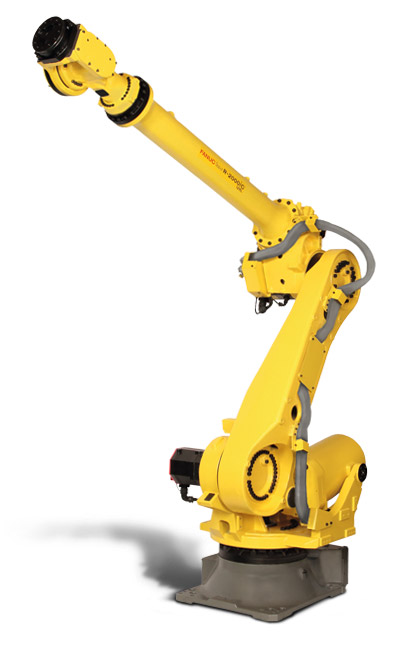

b) Capacidad de carga

125 kg

c) Alcance vertical y horizontal

3100 mm horizontal y 3490 mm vertical

d) Repetitibilidad

$\pm 0.05$mm basado en ISO9283

e) Gráfica(s) de espacio alcanzable

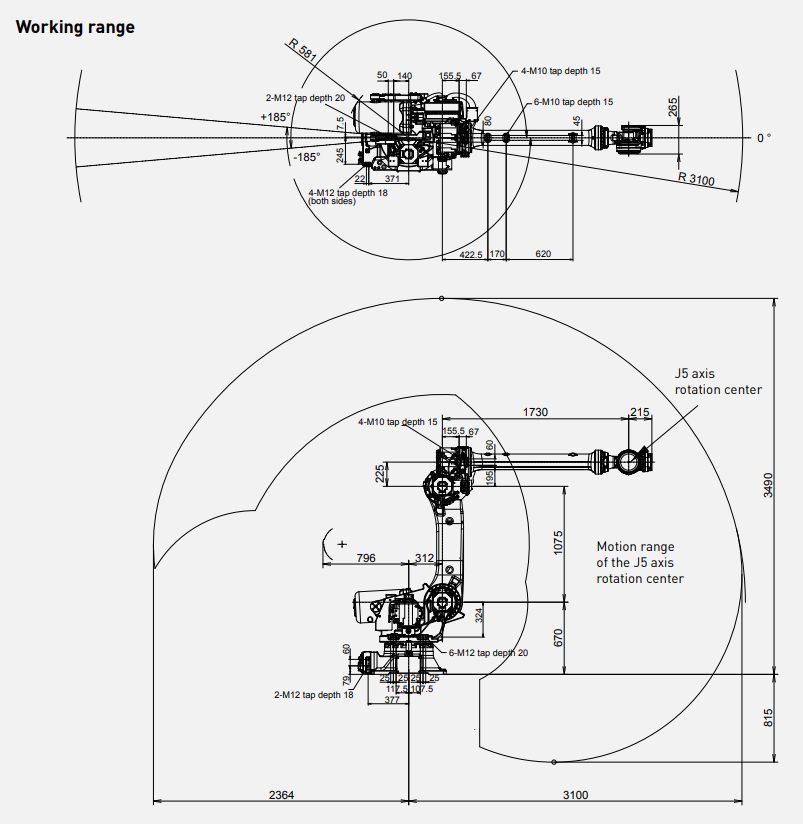

f) Tabla de parámetros DH

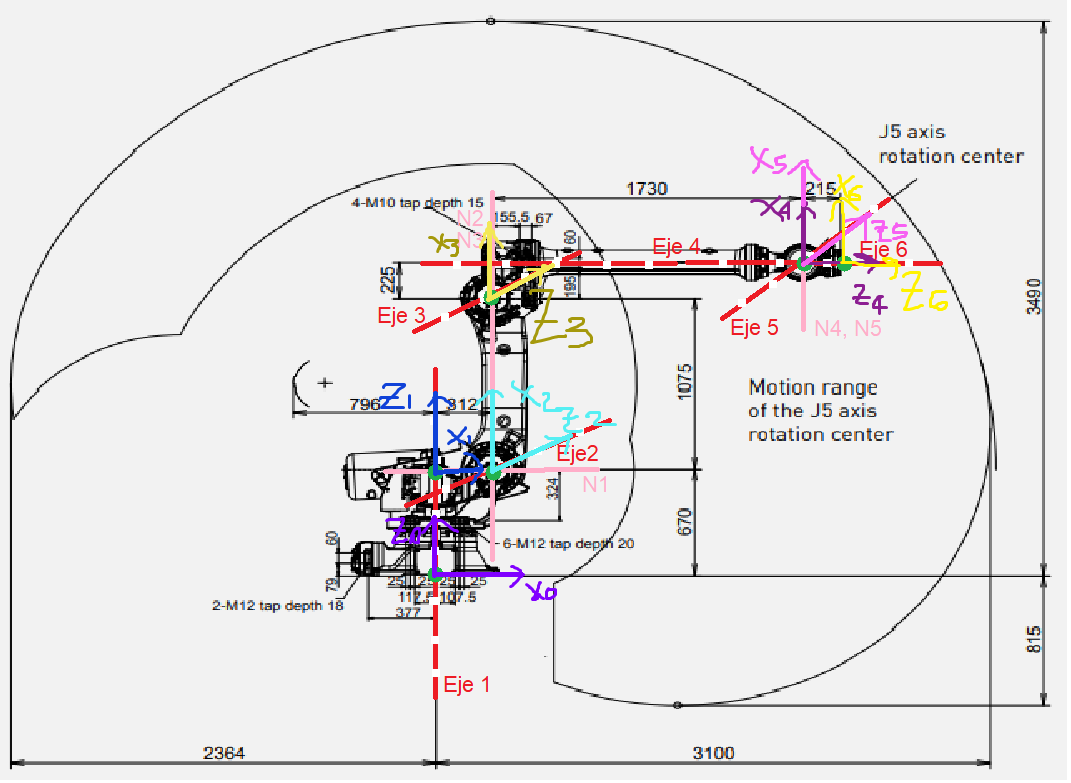

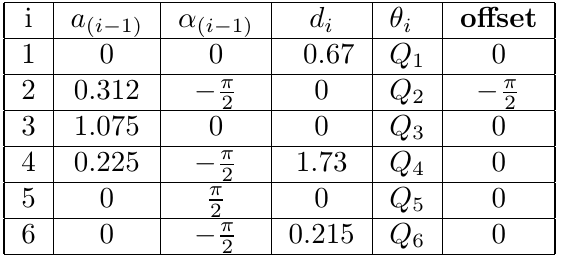

g) Qué software utiliza el fabricante para diseño de celdas o programación

Este modelo de robot está integrado en el software de programación offline de FANUC, ROBOGUIDE. ROBOGUIDE es una potente herramienta que permite a los integradores, planificadores y usuarios diseñar células, sistemas y simular movimientos offline.

h) ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.) 

Conexión eléctrica

Voltaje 50/60Hz trifásico 380-575 V

Consumo promedio de energía 2.5 kW

Suministro de aire integrado: 2

Nivel de ruido acústico 70.5 dB

Temperatura ambiente: 0-45 °C

Protección de cuerpo (estándar/opcional): IP54/IP56

Protección de muñeca brazo J3 (estándar/opcional): IP67 

i) Haga un análisis del diagrama de la capacidad de carga.

ESTO FALTA

2. Según las características anteriores explique para qué aplicaciones se usa este robot.

Es el robot adecuado para aplicaciones de carga pesada que requieran una repetibilidad excelente. Es el especialista en soldadura por puntos, gracias a su alto rendimiento, fácil instalación, diseño estilizado y gran cantidad de funciones adicionales, es la solución definitiva de soldadura. Como tiene elevada repetibilidad y una considerable carga de trabajo para aplicaciones de ensamble, transferencia de piezas, eliminación de material, servicio integrado  dispensado.

## Parte 2 - Modelos

### Iniciando

- Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

L(1) = Link('revolute','alpha',0,    'a', 0,    'd',0.67, 'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0,    'offset',-pi/2,...
    'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',1.73, 'offset',0, ...
    'modified', 'qlim',[0 5]);
L(5) = Link('revolute','alpha',pi/2,  'a', 0,   'd',0,    'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',-pi/2, 'a', 0,   'd',0.215,'offset',0, ...
    'modified', 'qlim',[-pi pi]);